Daniel Sklyar

Homework 02

Exercise 2

a) Check functions below this code block

b) and c) below

%format short;
% shorter format just decreases the legth of the decimal point
% to which number will be displayed. 
format long;
x = 1;
n = 1:10

n =      1     2     3     4     5     6     7     8     9    10


error = [];
for i = n
    fprintf('Calculating sin(%d) using Taylor with n = %d',x,i);
    actual = sin(x)
    calculated_sum = 0;
    for j = 0:i
        calculated_sum = calculated_sum + sine_Taylor(j,x);
    end 
    calculated_sum
    err = abs(sin(x) - calculated_sum)
    error(i + 1) = err;
end

Calculating sin(1) using Taylor with n = 1

actual =    0.841470984807897


calculated_sum =    0.833333333333333


err =    0.008137651474563


Calculating sin(1) using Taylor with n = 2

actual =    0.841470984807897


calculated_sum =    0.841666666666667


err =      1.956818587701692e-04


Calculating sin(1) using Taylor with n = 3

actual =    0.841470984807897


calculated_sum =    0.841468253968254


err =      2.730839642528515e-06


Calculating sin(1) using Taylor with n = 4

actual =    0.841470984807897


calculated_sum =    0.841471009700176


err =      2.489227990398746e-08


Calculating sin(1) using Taylor with n = 5

actual =    0.841470984807897


calculated_sum =    0.841470984648068


err =      1.598284837811548e-10


Calculating sin(1) using Taylor with n = 6

actual =    0.841470984807897


calculated_sum =    0.841470984808658


err =      7.619460618002449e-13


Calculating sin(1) using Taylor with n = 7

actual =    0.841470984807897


calculated_sum =    0.841470984807894


err =      2.775557561562891e-15


Calculating sin(1) using Taylor with n = 8

actual =    0.841470984807897


calculated_sum =    0.841470984807897


err =      0


Calculating sin(1) using Taylor with n = 9

actual =    0.841470984807897


calculated_sum =    0.841470984807897


err =      0


Calculating sin(1) using Taylor with n = 10

actual =    0.841470984807897


calculated_sum =    0.841470984807897


err =      0


d) below

range = 0:10

range =      0     1     2     3     4     5     6     7     8     9    10


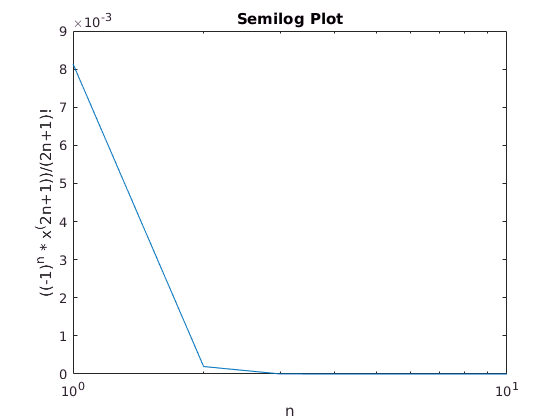

semilogx(range,error), hold on
ylabel('((-1)^n * x^(2n+1))/(2n+1)!');
xlabel('n');
title('Semilog Plot');
hold off;

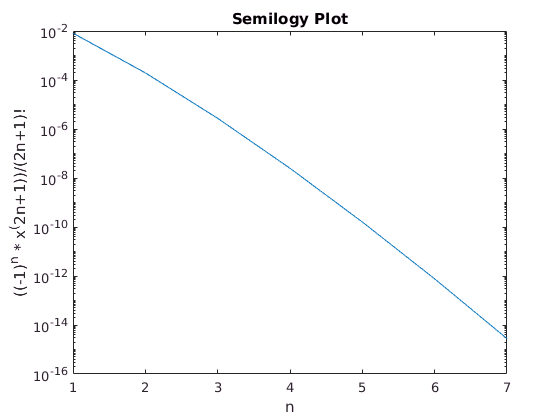

semilogy(range,error), hold on
ylabel('((-1)^n * x^(2n+1))/(2n+1)!');
xlabel('n');
title('Semilogy Plot');
hold off;

% Semilogy plot shows the best linear error decay
fprintf('Semilogy plot shows the best linear error decay');

Semilogy plot shows the best linear error decay

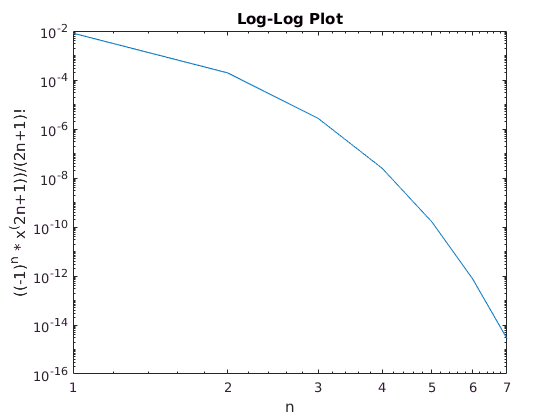

loglog(range,error), hold on
ylabel('((-1)^n * x^(2n+1))/(2n+1)!');
xlabel('n');
title('Log-Log Plot');
hold off

e) and f) below, also Semilogy plot shows the best linear error decay

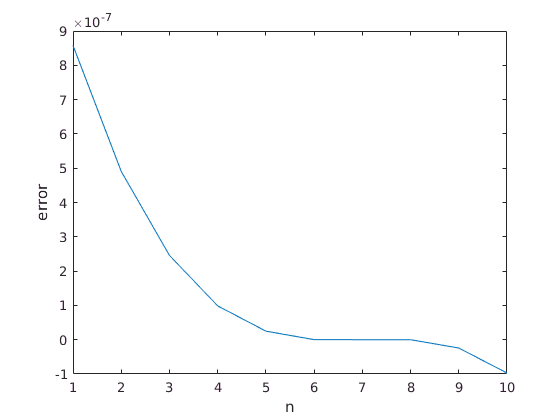

% getting the range 5:8 of error array to use it in polyfit
list = [];
counter = 1;
for i = 0:length(error)
    if i <= 8 && i >= 5
        list(counter) = error(i);
        counter = counter + 1;
    end
end
% using polyfit 
p = polyfit(5:8,list,3);
% evaluating the polynomial with n
y1 = polyval(p,n);
% ploting the error prediction for sine_Taylor
plot(n,y1);
xlabel('n');
ylabel('error');

g)

% after n = 9 the prediction curve goes into negative values suggesting
% that the approximization gets worse.

Exercise 3

a) is in the function block below

b)

format short;
x = 1.1; h = 0.01;
der_v1 = myderivative_v1(x);
der_v2 = myderivative_v2(x,h);
fprintf('Difference %f - %f = %f', der_v1,der_v2, der_v1 - der_v2);

Difference 0.200000 - 0.210000 = -0.010000

c)

h = 0.001;
der_v1 = myderivative_v1(x);
der_v2 = myderivative_v2(x,h);
fprintf('Difference %f - %f = %f', der_v1,der_v2, der_v1 - der_v2);

Difference 0.200000 - 0.201000 = -0.001000

d)

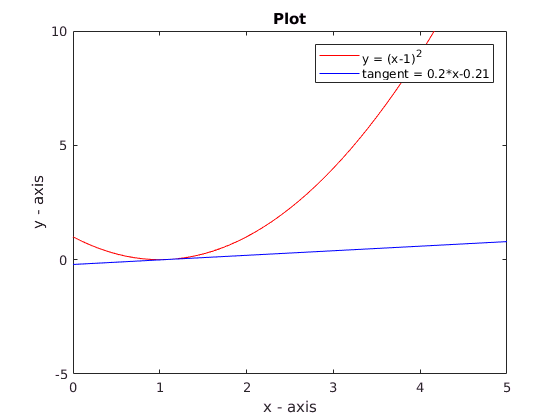

% y - y1 = m(x-x1)
% in this case dx/dy = 2(x-1) at x = 1.1 m wil lequal to 2(1.1-1) = 0.2
% x1 = 1.1 and y = (1.1-1)^2 = 0.01
% tangent = 0.2(x - 1.1) - 0.01 -> y = 0.2x - 0.22 - 0.01

x = 0:0.1:5;
y = (x-1).^2;
tangent = 0.2.*x - 0.21;
plot(x,y,'r')
hold on
plot(x,tangent,'b')
legend('y = (x-1)^2','tangent = 0.2*x-0.21')
xlabel('x - axis');
ylabel('y - axis');
title('Plot');
axis ( [0 5 -5 10] );
hold off

e) new tangent line is quite close to the original tangent but overstemates by a tiny fraction.

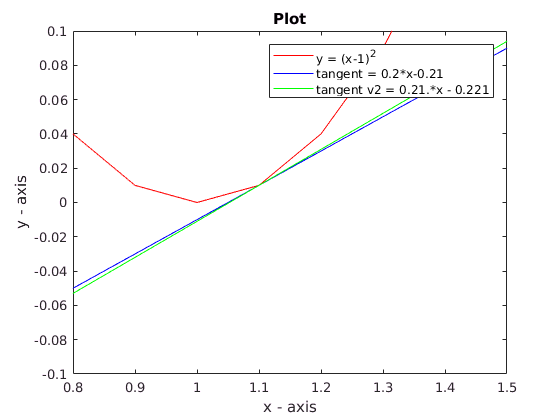


x = 1.1; h = 0.01;
der_v2 = myderivative_v2(x,h); 

x = 0:0.1:5;
y = (x-1).^2;
tangent = 0.2.*x - 0.21;

% y - y1 = m(x-x1)
% in this case  m wil lequal to der_v2 or 0.21
% x1 = 1.1 and y = (1.1-1)^2 = 0.01
% tangent_v1 = 0.21(x - 1.1) - 0.01 -> y = 0.21x - 0.231 - 0.01

tangent_v2 = 0.21.*x - 0.221;
plot(x,y,'r')
hold on
plot(x,tangent,'b')
hold on
plot(x,tangent_v2,'g')
legend('y = (x-1)^2','tangent = 0.2*x-0.21','tangent v2 = 0.21.*x - 0.221')
xlabel('x - axis');
ylabel('y - axis');
title('Plot');
axis ( [0.8 1.5 -.1 .1] );
hold off

function out = sine_Taylor(n,x)
    v1 = (-1).^n;
    v2 = x.^(2.*n+1);
    v3 = factorial(2.*n+1);
    out = (v1 .* v2) ./ v3;
end

function out = myderivative_v1(x)
    out = 2.*(x-1);
end
function out = myderivative_v2(x,h)
    out = ((((x + h)-1).^2)-((x-1).^2))./h;
end